# Riepilogo 02: calcoli dalla popolazione di valori di una v.a.

## 1 - Calcolo di momenti, media, varianza, MAD (calcoli da pdf)

Queste quantità sono calcolate dalla pdf della v.a., se nota

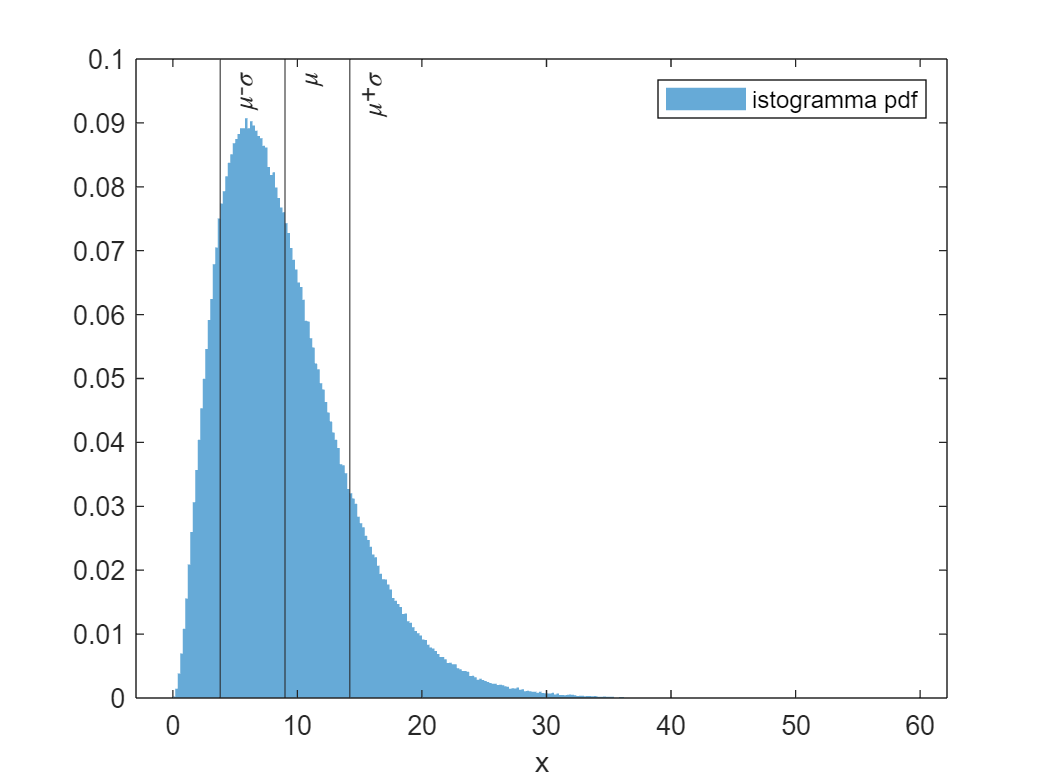

% Dati
% X = popolazione di valori (vettore riga)

% Domande
% m1 = momento di ordine 1 della v.a.
% m2 = momento di ordine 2 della v.a.
%
% mc1 = momento centrale di ordine 1 della v.a.
% mc1_teo = valore teorico che deve assumere mc1
% mc2 = momento centrale di ordine 2 della v.a.
% 
% mu = media della v.a.
% P = potenza della v.a.
% sigma2 = varianza della v.a.
% sigma = deviazione standard della v.a.
%
% MAD = mean absolute deviation della v.a.

% Nota: si considera il numero Nsim di elementi della popolazione 
% abbastanza grande da identificare i suoi momenti con le quantità 
% calcolate dalla pdf, e da poter considerare
% trascurabile la differenza tra Nsim e Nsim-1

% Codice iniziale
clear
rng('default') % per ripetibilità dei risultati
n = 3; mu1 = 3; % parametri della pdf
Nsim = 1e6;
X = gamrnd(n,mu1,[1,Nsim]);

### Soluzione


$$m_1 =\frac{1}{N_{\mathrm{sim}} }\sum_{n=1}^{N_{\mathrm{sim}} } X_n$$


$m_1 =\mu =E\left\lbrack X\right\rbrack$  per $N_{\mathrm{sim}}$ abbastanza grande

m1 = mean(X) % il momento di ordine 1 è la media aritmetica

m1 = 9.0048

Nsim = numel(X); m1 = sum(X)/Nsim % alternativa

m1 = 9.0048

mu = m1 % il valore atteso è il momento di ordine 1

mu = 9.0048


$$m_2 =\frac{1}{N_{\mathrm{sim}} }\sum_{n=1}^{N_{\mathrm{sim}} } X_n^2$$


$m_2 =P=E\left\lbrack X^2 \right\rbrack \;$  per $N_{\textrm{sim}}$ abbastanza grande

m2 = mean(X.^2) % momento di ordine 2

m2 = 108.1078

m2 = sum(X.^2)/Nsim % alternativa

m2 = 108.1078

P = m2 % la potenza è il momento di ordine 2

P = 108.1078


$${mc}_1 =\frac{1}{N_{\mathrm{sim}} }\sum_{n=1}^{N_{\mathrm{sim}} } \left(X_n -\mu \;\right)$$



$${mc}_2 =0$$


mc1 = mean(X-m1) % anche mc1 = 0 è una risposta corretta

mc1 = -1.1946e-15

mc1_teo = 0 % il momento centrale di ordine 1 è nullo

mc1_teo = 0


$${mc}_2 =\frac{1}{N_{\mathrm{sim}} }\sum_{n=1}^{N_{\mathrm{sim}} } {\left(X_n -\mu \;\right)}^2 =P-\mu^2 =\sigma^2$$


mc2 = mean((X-mu).^2)

mc2 = 27.0212

mc2 = P - mu^2 % alternativa

mc2 = 27.0212

sigma2 = mc2 % la varianza è il momento centrale di ordine 2

sigma2 = 27.0212

sigma2 = var(X) % alternativa

sigma2 = 27.0212

% var() divide per Nsim-1, e non per Nsim come mean()
% Poiché Nsim è molto grande, la differenza qui è considerata trascurabile

sigma = sqrt(sigma2) % la deviazione standard è la sqrt della varianza

sigma = 5.1982

sigma = std(X) % alternativa

sigma = 5.1982

% std() divide per Nsim-1, e non per Nsim come mean()
% Poiché Nsim è molto grande, la differenza qui è considerata trascurabile


$$MAD=\frac{1}{N_{\mathrm{sim}} }\sum_{n=1}^{N_{\mathrm{sim}} } |X_n -\mu |$$


MAD = mean(abs(X-mu))

MAD = 4.0363

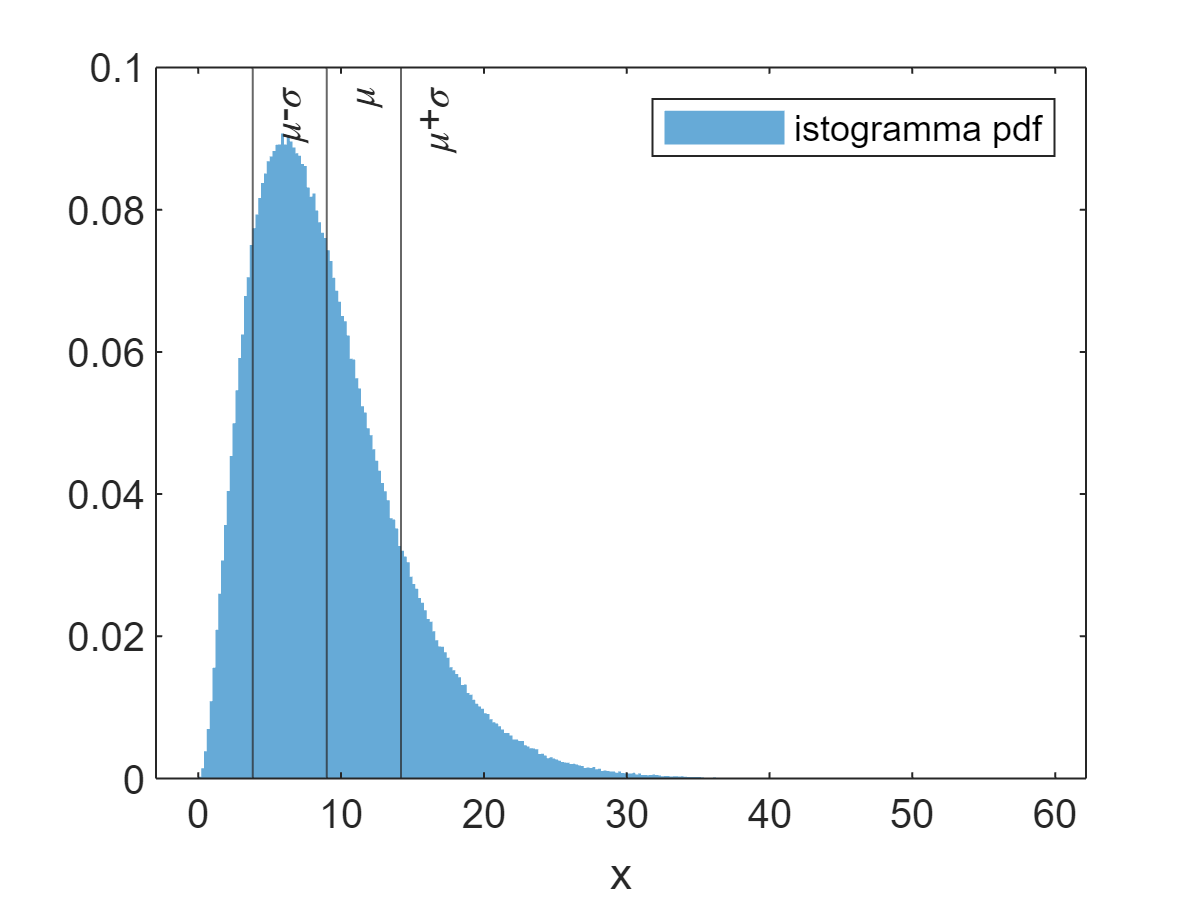

% Grafico nella traccia
histogram(X,'Normalization','pdf','EdgeColor','none')
xline(mu,'-','\mu')
xline(mu+sigma,'-','\mu+\sigma')
xline(mu-sigma,'-','\mu-\sigma')
xlabel('x')
legend('istogramma pdf')

## 2 - Calcolo di probabilità di intervalli (calcoli da cdf)

Queste quantità sono calcolate dalla cdf della v.a., se nota

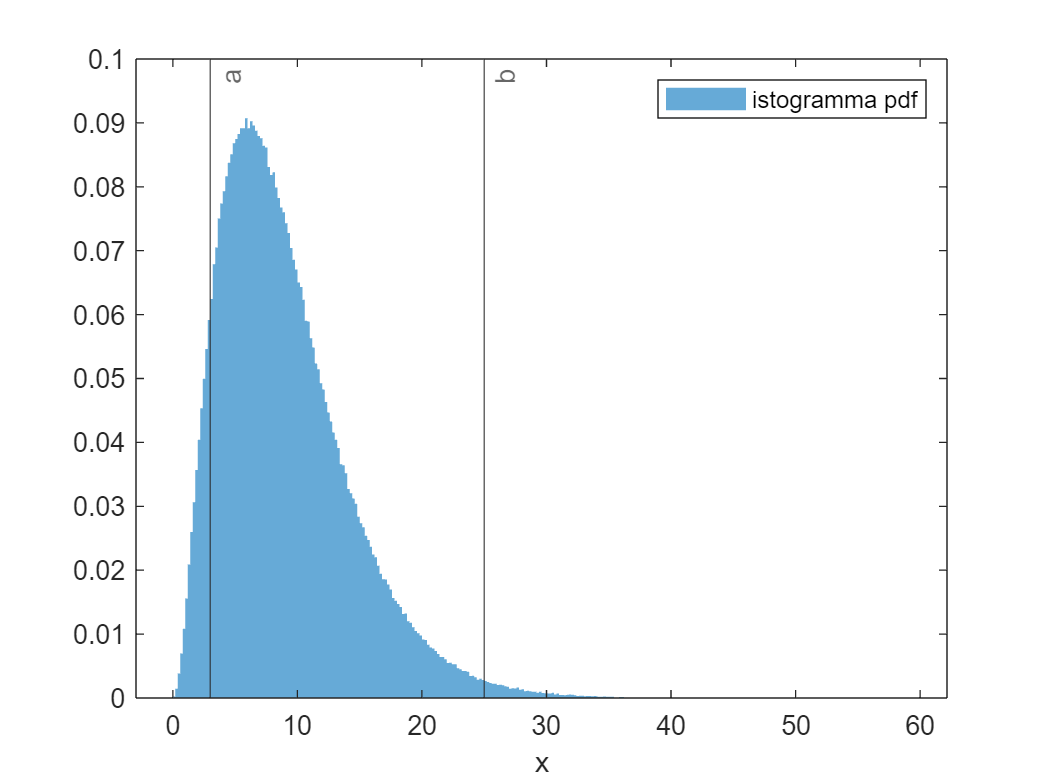

% Dati
% X = popolazione di valori (vettore riga)
% a = valore assegnato (scalare)
% b = valore assegnato maggiore di a (scalare)

% Domande
% Pa = Prob(X = a)
% Pb = Prob(X = b)
% Pab = Prob(X in [a,b]) (probabilità che X assuma un valore compreso tra a e b)
% Pab_not = Prob(X not in [a,b]) (probabilità che X NON assuma un valore compreso tra a e b)
% Pa_minore = Prob(X <= a) probabilità che X assuma valore <= a
% Pa_maggiore = Prob(X >= a) probabilità che X assuma valore >= a

% Nota:
% Questo esercizio è tutto basato sulla capacità di contare il numero di volte
% che si verifica una certa condizione, ad esempio X==a, (X>=a & X <=b), ecc.
% Si considera il numero N di elementi di X abbastanza grande da poter calcolare
% le probabilità come "frequenze relative" di eventi.

% Codice iniziale
clear
rng('default') % per ripetibilità dei risultati
n = 3; mu1 = 3; % parametri della pdf
Nsim = 1e6;
X = gamrnd(n,mu1,[1,Nsim]);

a = 3; b = 25; % valori

### Soluzione

$\mathrm{Prob}\left(X=a\right)=\frac{#\left(X=a\right)}{N}$ per $N$ abbastanza grande

Quindi abbiamo bisogno del numero N di elementi di X

N = numel(X) % numero di elementi di X

N = 1000000

Per contare il numero di volte in cui si verifica una condizione, devo scrivere:

Ad esempio, per contare il numero di volta in cui X > a si scrive:

Na = sum(X==a) % numero di "1" nel vettore 0-1 (X==a), che è =1 dove X=a

Na = 0


$$\mathrm{Prob}\left(X=a\right)=\frac{#\left(X=a\right)}{N}$$


Pa = Na/N

Pa = 0

Pa = 0 % alternativa perfettamente accettata

Pa = 0

Nb = sum(X==b) % numero di "1" nel vettore 0-1 che è =1 dove X=b

Nb = 0

Pb = Nb/N

Pb = 0

Pb = 0 % alternativa perfettamente accettata

Pb = 0


$$\mathrm{Prob}\left(X\in \left\lbrack a,b\right\rbrack \right)=\frac{#\left(X\in \left\lbrack a,b\right\rbrack \right)}{N}$$


Nab = sum(X>=a & X<=b) % conta quante volte X>=a AND X<=b

Nab = 909126

Pab = Nab/N

Pab = 0.9091

Pab_not = 1 - Pab

Pab_not = 0.0909

Alternativa: $\mathrm{Prob}\left(X\not\in \;\left\lbrack a,b\right\rbrack \right)=\frac{#\left(X\not\in \;\left\lbrack a,b\right\rbrack \right)}{N}$ 

Nab_not = sum(X<a | X>b) % conta quante volte X<a OR X>b

Nab_not = 90874

Pab_not = Nab_not/N % alternativa

Pab_not = 0.0909

Na_minore = sum(X<=a) % conta quante volte X<=a

Na_minore = 80315

Pa_minore = Na_minore/N % Prob(X<=a)

Pa_minore = 0.0803

Pa_maggiore = 1 - Pa_minore

Pa_maggiore = 0.9197

Na_maggiore = sum(X>=a) % alternativa: conta quante volte X>=a

Na_maggiore = 919685

Pa_maggiore = Na_maggiore/N % Prob(X>=a)

Pa_maggiore = 0.9197

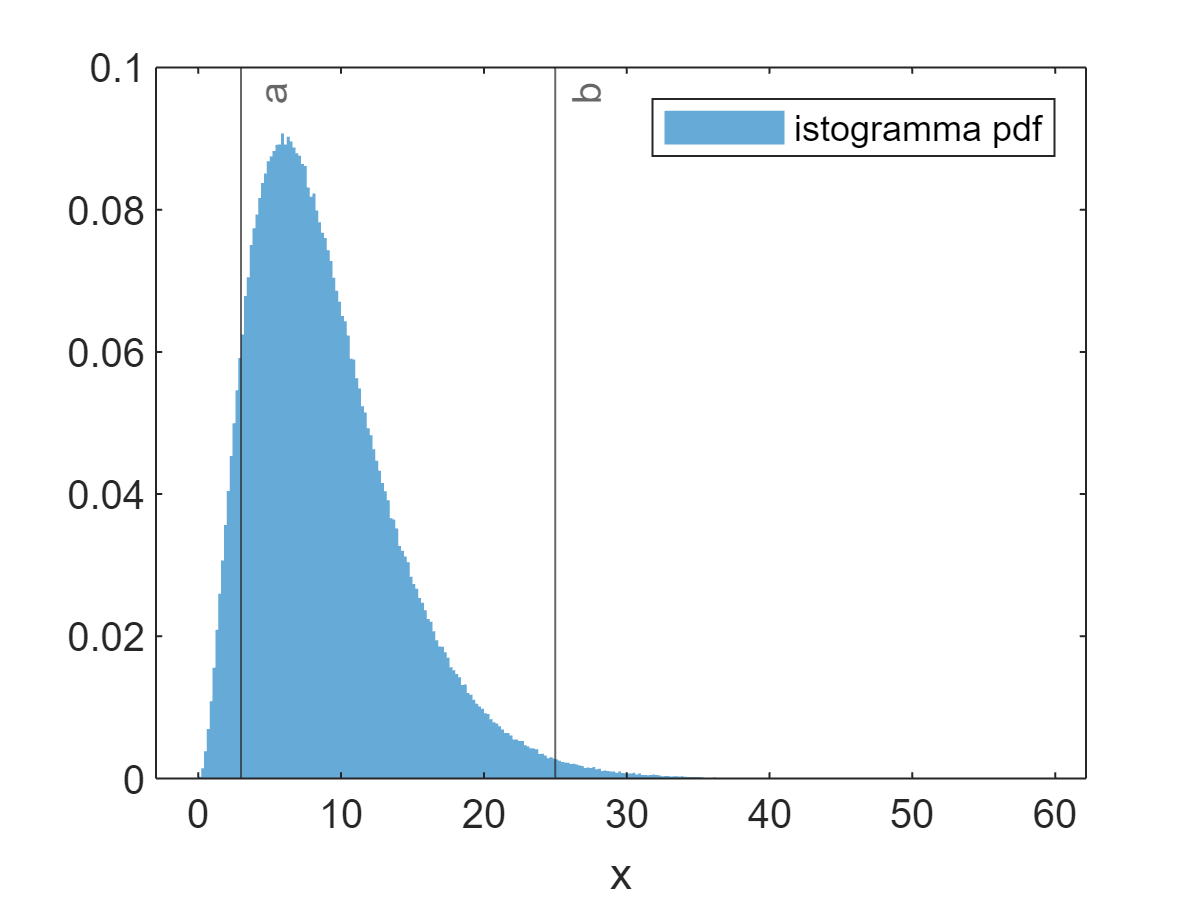

% Grafico nella traccia
histogram(X,'Normalization','pdf','EdgeColor','none')
xline(a,'-','a')
xline(b,'-','b')
xlabel('x')
legend('istogramma pdf')

## 3 - Calcolo di intervalli data la probabilità (calcoli da icdf)

Queste quantità sono calcolate dalla icdf della v.a., se nota

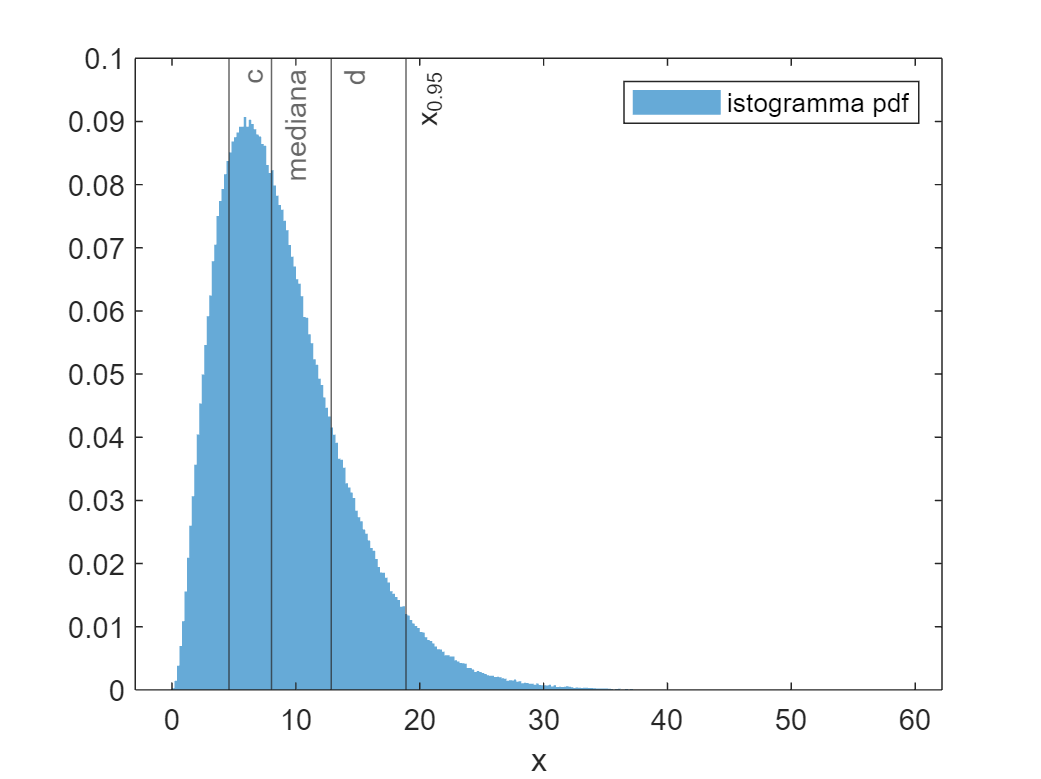

% Dati
% X = popolazione di valori (vettore riga)
% p_left = probabilità a sinistra dell'intervallo da calcolare
% p = probabilità dell'intervallo da calcolare

% Domande
% a = estremo sinistro dell'intervallo di prob. p con probabilità a sinistra p_left
% b = estremo destro dell'intervallo di prob. p con probabilità a sinistra p_left
%
% c = estremo sinistro dell'intervallo di prob. p *a code di area uguale*
% d = estremo destro dell'intervallo di prob. p *a code di area uguale*
%
% q1 = primo quartile della v.a.
% q2 = secondo quartile della v.a.
% q3 = terzo quartile della v.a.
% mediana = mediana della v.a.
% IQR = range interquartile della v.a.
% x95 = quantile 0.95 della v.a. = 95° percentile della v.a.

% Codice iniziale
clear
rng('default') % per ripetibilità dei risultati
n = 3; mu1 = 3; % parametri della pdf
Nsim = 1e6;
X = gamrnd(n,mu1,[1,Nsim]);

p_left = 0.1;
p = 0.6;

### Soluzione


$$a=x_{p_{\mathrm{left}} } =F^{-1} \left(p_{\mathrm{left}} \right)$$
 


$$b=x_{p_{\mathrm{left}} +p} =F^{-1} \left(p_{\mathrm{left}} +p\right)$$
 

a = quantile(X,p_left)

a = 3.3060

b = quantile(X,p+p_left)

b = 10.8544

c = quantile(X,(1-p)/2)

c = 4.6012

d = quantile(X,(1+p)/2)

d = 12.8504

q1 = quantile(X,0.25)

q1 = 5.1804

q2 = quantile(X,0.5)

q2 = 8.0306

q3 = quantile(X,0.75)

q3 = 11.7680


mediana = q2

mediana = 8.0306

IQR = q3-q1

IQR = 6.5876

x95 = quantile(X,0.95)

x95 = 18.8910

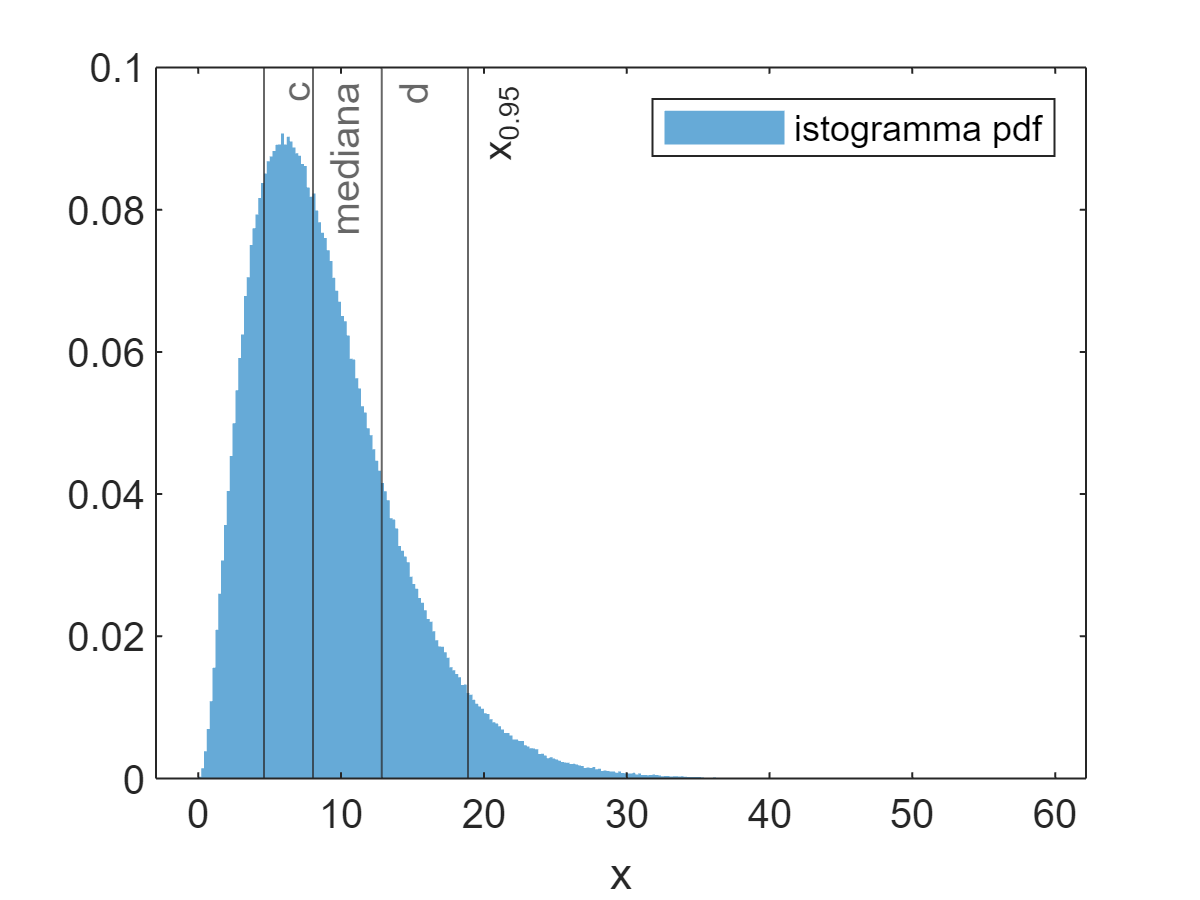

% Grafico nella traccia
histogram(X,'Normalization','pdf','EdgeColor','none')
xline(c,'-','c')
xline(d,'-','d')
xline(mediana,'-','mediana')
xline(x95,'-','x_{0.95}')
xlabel('x')
legend('istogramma pdf')